`In the name of God`

# Blind Source Separation

# Homework #12

**Ashkan Jafari**

**810197483**

## 1)

### Generating Dictionary

mut_coh = 1;
M = 3;
N = 6;
while mut_coh > 0.9
    dictionary = zeros(M,N);
    dictionary = initialize_dictionary(dictionary,N,M);
    mut_coh = mutual_coherence(dictionary);
end

### Generating Source

% Through each time point ([1,1000]) one of the sources is on ([1,6])
idx = randi([1,6],[1,1000]);
sparce_value = unifrnd(-5,5,1,1000);
source = zeros(6,1000);
for time_point = 1:1000
    s_t = zeros(6,1);
    source_which_is_on = idx(time_point);
    s_t(source_which_is_on) = sparce_value(time_point);
    source(:,time_point) = s_t;
end

### Generating Noise

noise_sens1 = normrnd(0,0.01,1,1000);
noise_sens2 = normrnd(0,0.01,1,1000);
noise_sens3 = normrnd(0,0.01,1,1000);

noise = [noise_sens1;noise_sens2;noise_sens3];

### Generating Observation

observation = dictionary*source+noise;

### A) ScatterPlot Method

- The scatter plot should show 6 clusters (vectors), which are the dictionary columns. 

- At a time-point each sample of $x\left(t\right)$, must be projected on each of these vectors. The one with the highest projection indicates the corresponding source to be "on" and the value of projection will be the sparce-value. (Note that above explainations are true when Dictionaries Columns are presumed to be unit-norm.)

- With this method Dictionary will not be found uniquely. Because this approach has inherent permutation ambiguity of BSS problems. 

- The inherent permutation ambiguity is not important; because here only the source separation matters!

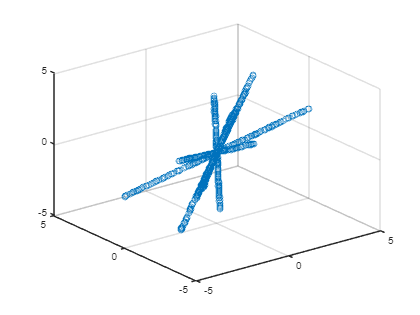

X1 = observation;
scatter3(X1(1,:),X1(2,:),X1(3,:))

### B) MOD Method

% initializing a Dictionary
init_D = zeros(M,N);
init_D = initialize_dictionary(init_D,N,M);
D_hat = init_D;

% Iterations
for iter = 1:20
    % D is fixed
    S_hat = MP(X1,D_hat);
   
    % S is fixed
    D_hat = X1*pinv(S_hat);
    for j = 1:6
        D_hat(:,j) = D_hat(:,j)/norm(D_hat(:,j));
    end
end

MOD_SRR = successful_recovery_rate(dictionary,D_hat,0.99)

MOD_SRR = 66.6667

### C) K-SVD Method

D_hat2 = init_D;

for iter = 1:20
    % D is fixed
    S_hat2 = MP(X1,D_hat2);
    
    % S is fixed
    D_hat2 = zeros(3,6);
    for j = 1:6
        for i = 1:3
            D_hat2(i,j) = normrnd(0,1);
        end
        D_hat2(:,j) = D_hat2(:,j)/norm(D_hat2(:,j));
    end
    
    for c = 1:6
        Xr = X1-[D_hat2(:,1:c-1),D_hat2(:,c+1:6)]*[S_hat2(1:c-1,:);S_hat2(c+1:6,:)];
        Xr_m = (S_hat2(c,:) ~= 0).*Xr;
        [U,G,V] = svd(Xr_m);
        D_hat2(:,c) = transpose(U(:,1));
    end
end

KSVD_SRR = successful_recovery_rate(dictionary,D_hat2,0.99)

KSVD_SRR = 50

### D)

All we do is that we consider all permutations and calculate the Error for each permutation. Then the minimum error will be the error for the correct permutation.

MOD_Error = permutation_problem(S_hat,source,6)

MOD_Error = 1.9262

KSVD_Error = permutation_problem(S_hat2,source,6)

KSVD_Error = 1.4521

## 2)

clear;
clc;
load('hw12.mat');
dictionary2 = D;
source2 = S;
X2 = X;

### A) MOD Method

N0 = 3;
% initializing a Dictionary
M = 20;
N = 50;
init_D = zeros(M,N);
init_D = initialize_dictionary(init_D,N,M);

D_hat_p2 = init_D;

for iter = 1:30
    % D is fixed
    S_hat_p2 = OMP(X2,D_hat_p2,3);

    % S is fixed
    D_hat_p2 = X2*pinv(S_hat_p2);
    for j = 1:50
        D_hat_p2(:,j) = D_hat_p2(:,j)/norm(D_hat_p2(:,j));
    end
    f = X2 - D_hat_p2*source2;
    f1(iter) = norm(f)/norm(X2);;
end

MOD_p2_SRR = successful_recovery_rate(dictionary2,D_hat_p2,0.6)

MOD_p2_SRR = 62

### B) K-SVD Method

D_hat2_p2 = init_D;

for iter = 1:30
    % D is fixed
    S_hat2_p2 = OMP(X2,D_hat2_p2,3);
    
    % S is fixed
    D_hat2_p2 = zeros(M,N);
    for j = 1:50
        for i = 1:M
            D_hat2_p2(i,j) = normrnd(0,1);
        end
        D_hat2_p2(:,j) = D_hat2_p2(:,j)/norm(D_hat2_p2(:,j));
    end
    
    % Updating each column of the dictionary one by one
    for c = 1:N
        Xr = X2-[D_hat2_p2(:,1:c-1),D_hat2_p2(:,c+1:50)]*[S_hat2_p2(1:c-1,:);S_hat2_p2(c+1:50,:)];
        Xr_m = (S_hat2_p2(c,:) ~= 0).*Xr;
        [U,G,V] = svd(Xr_m);
        D_hat2_p2(:,c) = transpose(U(:,1));
    end
    f = X2 - D_hat2_p2*source2;
    f2(iter) = norm(f)/norm(X2);
end

srr_K_SVD_p2 = successful_recovery_rate(dictionary2,D_hat2_p2,0.6)

srr_K_SVD_p2 = 82

**First I change the treshold from 0.99 to 0.6 inorder to see the difference between K-SVD and MOD.**

**As it is showed above SRR in K-SVD is 82 while in MOD is 62.**

**But as we have learned in the course, K-SVD would have a better performance because It updates Dictionary matrix colum by column which means the second column should be updated after and based on the first column. While in MOD we update Dictionary's columns simultaneously. **

**Cost-Function (f) = **${||X-\overset{\wedge }{D} S||}_2 \;$

**I think If we want to have the precise cost-function we should first eliminate the permutation ambguity but here because we have 50 sources, so Matlab doesnt let us to create perms(1:50)!! **

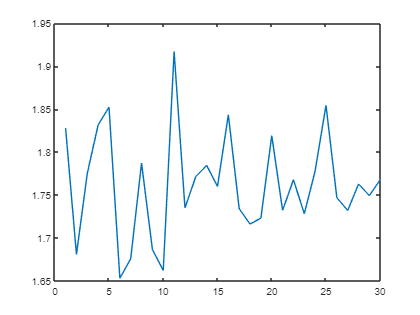

plot(f2) % K-SVD

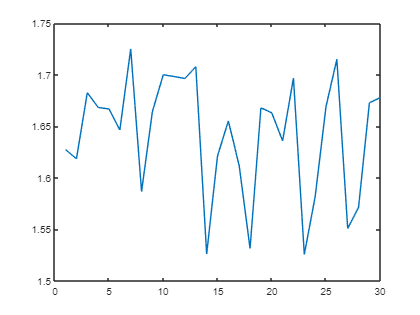

plot(f1) % MOD

## Functions.

function mc = mutual_coherence(M)
mc = 0;
for i = 1:size(M,2)
    for j = i:size(M,2)
       if i ~= j
           mu = transpose(M(:,i))*M(:,j);
           if mu > mc
               mc = mu;
           end
       end
    end
end
end

function dictionary = initialize_dictionary(dictionary,N,M)

for j = 1:N 
        for i = 1:M
            dictionary(i,j) = normrnd(0,1); % Generating each element
        end
        dictionary(:,j) = dictionary(:,j)/norm(dictionary(:,j)); % Normalizing
end
end

function srr = successful_recovery_rate(D,D_hat,percentage)
recovered = 0;
for i = 1:size(D_hat,2)
    mu = zeros(1,size(D,2));
    for j = 1:size(D,2)
       mu(j) = abs(transpose(D_hat(:,i))*D(:,j));
    end
    [val,ind] = max(mu);
    if val > percentage
        recovered = recovered+1;
        D(:,ind) = [];
    end
end
srr = recovered/size(D_hat,2)*100;
end

function E = permutation_problem(S_hat,S,n)
v = 1:n;
p = perms(v);
E = 100;
for i = 1:size(p,1)
    S_m = zeros(6,1000);
    for j = 1:6
        S_m(j,:) = S_hat(p(i,j),:);
    end
    E = min(E,norm(S_m-S)^2/norm(S)^2);
end
end

function S_hat = MP(X,D)
C = X'*D;
S_hat = zeros(6,1000);
for i = 1:size(C,1)
    [val,ind] = max(C(i,:));
    S_hat(ind,i) = val;
end
end

function S_hat = OMP(X,D,N0)
S_hat = zeros(50,1500);
for i = 1:1500
    xi = X(:,i);
    xr = xi;
    D1 = [];
    S1 = [];
    idx = zeros(1,3);
    for n = 1:N0
        C = xr'*D;
        [val,ind] = max(C);
        idx(n) = ind;
        D1 = [D1,D(:,ind)];
        S1 = pinv(D1)*xr;
        xr = xr-D1*S1;
    end
    for n = 1:N0
        S_hat(idx(n),i) = S1(n);
    end
end
end


